姓名：莊璧如 學號：111321534

ex1

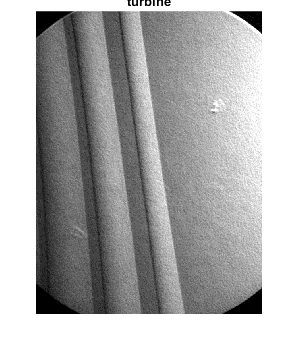

turbine=imread("turbine_blade_black_dot.tif");
imshow(turbine,[])
title('turbine')

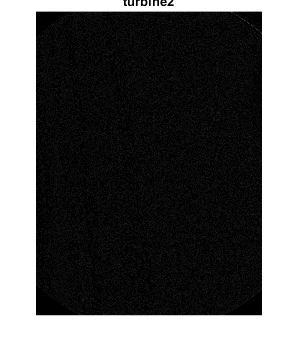

t=[-1 -1 -1;-1 8 -1;-1 -1 -1];
turbine2=filter2(t,turbine,'valid');
imshow(abs(turbine2),[])
title('turbine2')

turbine3= 0.9*max(abs(turbine2(:)));
imshow(abs(turbine3),[])

ex2

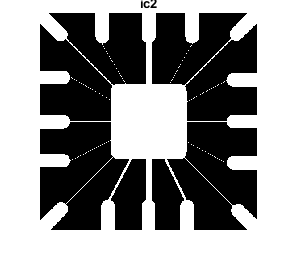

ic2=imread("ic2.tif");
imshow(ic2,[])
title('ic2')

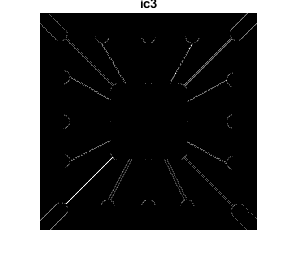

t1=[-1 -1 2;-1 2 -1;2 -1 -1];
ic3=filter2(t1,ic2,"valid");
imshow(abs(ic3),[])
title('ic3')

ex3

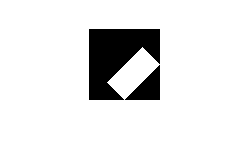

I1=[zeros(50, 25), 255*ones(50,25)]';
I1=imrotate(I, 45);
imshow(I,[])

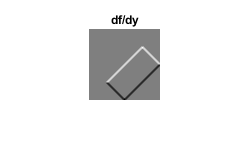

t2=[-1 -1 -1; 0 0 0; 1 1 1];
I2=filter2(t2,I1,"same");
imshow(I2,[])
title('df/dy')

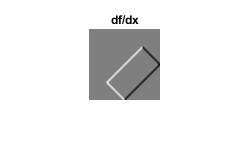

t3=[-1 0 1; -1 0 1; -1 0 1];
I3=filter2(t3,I1,"same");
imshow(I3,[])
title('df/dx')

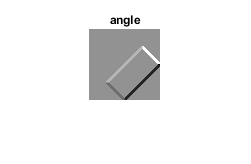

I4=atan2(I2,I3);
imshow(I4,[])
title('angle')

ex4

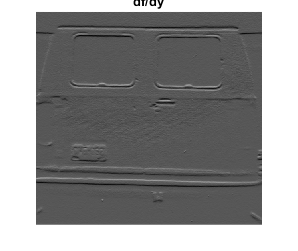

van=imread("van_original.tif");
t2=[-1 -1 -1; 0 0 0; 1 1 1];
van2=filter2(t2,van,"same");
imshow(van2,[])
title('df/dy')

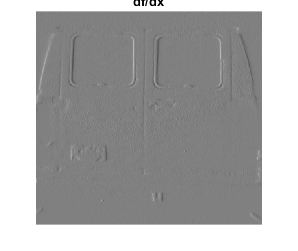

t3=[-1 0 1; -1 0 1; -1 0 1];
van3=filter2(t3,van,"same");
imshow(van3,[])
title('df/dx')

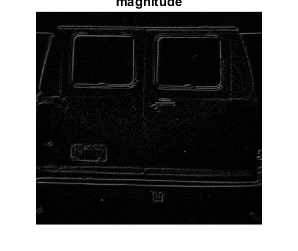

imshow(abs(van2+van3),[])
title('magnitude')

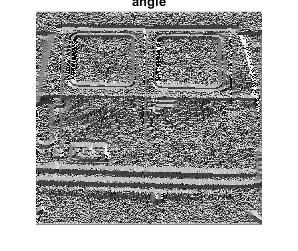

van4=atan2(van2,van3);
imshow(van4,[])
title('angle')

ex5

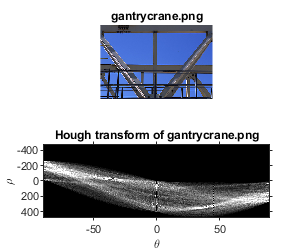

RGB = imread('gantrycrane.png');
I = rgb2gray(RGB); % convert to intensity
BW = edge(I,'canny'); % extract edges
[H,T,R] = hough(BW,'RhoResolution',0.5,'Theta',-90:0.5:89.5);
% display the original image
subplot(2,1,1);
imshow(RGB);
title('gantrycrane.png');
% display the hough matrix
subplot(2,1,2);
imshow(imadjust(mat2gray(H)),'XData',T,'YData',R,...
'InitialMagnification','fit');
title('Hough transform of gantrycrane.png');
xlabel('\theta'), ylabel('\rho');
axis on, axis normal, hold on;

%colormap(gca,hot);

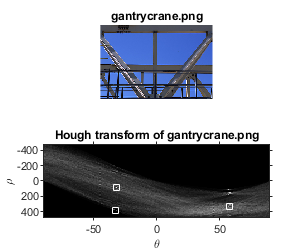

I = imread('van_original.tif');
rotI = imrotate(I,33,'crop');
BW = edge(rotI,'canny');
[H,T,R] = hough(BW);
imshow(H,[],'XData',T,'YData',R,'InitialMagnification','fit');xlabel('\theta'), ylabel('\rho');
axis on, axis normal, hold on;
P = houghpeaks(H,5,'threshold',ceil(0.3*max(H(:))));
x = T(P(:,2));
y = R(P(:,1));
plot(x,y,'s','color','white');

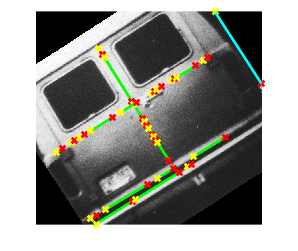

% Find lines and plot them
lines = houghlines(BW,T,R,P,'FillGap',5,'MinLength',7);
figure, imshow(rotI), hold on
max_len = 0;
for k = 1:length(lines)
xy = [lines(k).point1; lines(k).point2];
plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');
% plot beginnings and ends of lines
plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');
% determine the endpoints of the longest line segment
len = norm(lines(k).point1 - lines(k).point2);
if ( len > max_len)
max_len = len;
xy_long = xy;
end
end
% highlight the longest line segment
plot(xy_long(:,1),xy_long(:,2),'LineWidth',2,'Color','cyan');